clear
clc
t=linspace(0,2*pi,1000)';
a=2

a = 2

R=1

R = 1

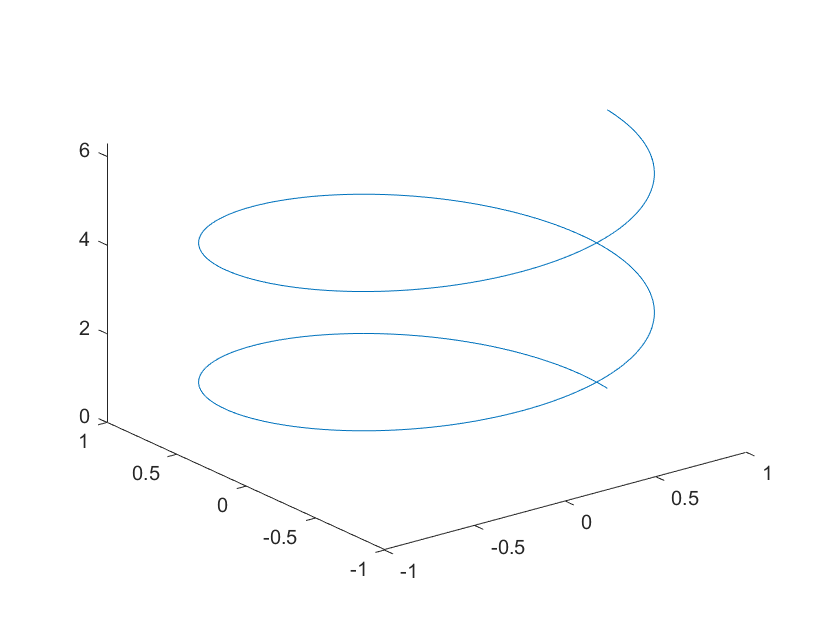

x_=cos(a*t);
y_=sin(a*t);
z_=t;
r=R*[x_,y_,z_];
figure,plot3(x_,y_,z_)
hold on

drawnow


drdu =    -0.0126    1.9999    1.0000
   -0.0377    1.9996    1.0000
   -0.0629    1.9990    1.0000
   -0.0880    1.9980    1.0000
   -0.1131    1.9968    1.0000
   -0.1383    1.9952    1.0000
   -0.1633    1.9933    1.0000
   -0.1884    1.9911    1.0000
   -0.2134    1.9886    1.0000
   -0.2384    1.9857    1.0000


That =    -0.0056    0.8944    0.4472
   -0.0169    0.8943    0.4472
   -0.0281    0.8940    0.4472
   -0.0394    0.8936    0.4472
   -0.0506    0.8930    0.4472
   -0.0618    0.8923    0.4472
   -0.0730    0.8914    0.4472
   -0.0843    0.8904    0.4472
   -0.0955    0.8893    0.4472
   -0.1066    0.8880    0.4472


N =    -1.7887   -0.0225         0
   -1.7883   -0.0450   -0.0000
   -1.7876   -0.0675    0.0000
   -1.7866   -0.0900   -0.0000
   -1.7853   -0.1124         0
   -1.7837   -0.1349         0
   -1.7819   -0.1573    0.0000
   -1.7798   -0.1797   -0.0000
   -1.7774   -0.2021    0.0000
   -1.7747   -0.2244   -0.0000


Nhat =   -71.0998   -0.8944         0
  -71.0830   -1.7887   -0.0000
  -71.0548   -2.6827    0.0000
  -71.0155   -3.5762   -0.0000
  -70.9649   -4.4692         0
  -70.9030   -5.3615         0
  -70.8300   -6.2529    0.0000
  -70.7457   -7.1434   -0.0000
  -70.6503   -8.0327    0.0000
  -70.5436   -8.9208   -0.0000


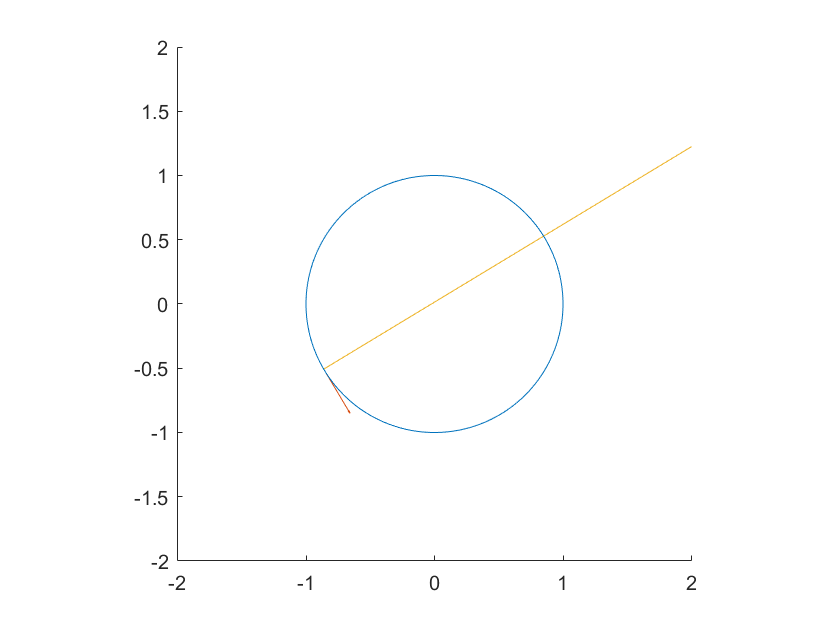

drdu = diff(r)./diff(t) 
That = drdu./sqrt(sum(drdu.^2,2))
N = diff(That)./diff(t(1:end-1)) 
Nhat = N./sqrt(sum(diff(drdu).^2,2))


for i = 1:length(t)-2
    clf
    hold on
    plot3(r(:,1),r(:,2),r(:,3)) % plot the entire path
    quiver(r(i,1),r(i,2),That(i,1),That(i,2),That(i,3)) % plot That
    quiver(r(i,1),r(i,2),Nhat(i,1),Nhat(i,2),Nhat(i,3)) % plot Nhat
    axis equal % equal axis so that it looks lke a circle
    axis([-2 2 -2 2]) % plot domain large enough to see what is going on
    drawnow % force the plotting otherwise it will plot everything at once
end